close all; clear; clc;

# 90% Settling time test used for inertia capturing test

SetTimev2TMotor15d: NAME.mlx

**keywords:** 

**file created by:** {YYYYMMDD, NAME}

**last updated on:** {YYYYMMDD}

**primary purpose:** {Enter the primary purpose and primary input and output variables.}

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** [C_T], [C_P], [C_Q]

**Notes:** 

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
p = 0.00230753800989592;                  %[slugs/ft^3]

% Motor Specs
radius = 7.5/12;               % [ft]
area = pi * radius^(2);       % [ft^2]

## Measured Data

This format assumes that the "servo" column was deleted beforehand

load('SetTimev2TMotor15d.mat');
time = SetTimev2TMotor15d(:,1);          % [sec]
ESC_us = SetTimev2TMotor15d(:,2);        % [micro sec] (this is how quickly the ESC is providing voltage to the motor -- translates to throttle% ?
Q = SetTimev2TMotor15d(:,3);             % [ft.lbf]
T = SetTimev2TMotor15d(:,4);             % [lbf]
Input_V = SetTimev2TMotor15d(:,5);       % [Volts]
Input_A = SetTimev2TMotor15d(:,6);       % [Amps]
rot_speed = SetTimev2TMotor15d(:,7);     % [rad/sec]
P_in_W = SetTimev2TMotor15d(:,8);        % [Watts]
P_out_W = SetTimev2TMotor15d(:,9);        % [Watts]
% convert to [ft.lbf/sec]
P_out = P_out_W .* 0.7478;     % [ft.lbf/sec]         
P_in = P_in_W .* 0.7478;       % [ft.lbf/sec]

Motor_Eff = SetTimev2TMotor15d(:,10);    % [%]
Prop_Eff = SetTimev2TMotor15d(:,11);     % [lbf/Watts]
Overall_Eff = SetTimev2TMotor15d(:,12);  % [lbf/Watts]  
Motor_Temp = SetTimev2TMotor15d(:,13);   % [F]



Settling_time = SetTimev2TMotor15d(:,14); % [s]
Max_Acc = SetTimev2TMotor15d(:,15);      % [RPM]

rot_speed_rpm = rot_speed / (pi / 30);

## Thrust, Power, and Torque Coefficents

C_T = T ./ (p .* area * (rot_speed * radius).^2);
C_P = P_out ./ (p .* area .* (rot_speed .* radius).^3);
C_Q = Q ./ (p .* area .* (rot_speed .* radius).^(2) .* radius);

## Plots

{This is the section for generating output tables, plots, etc.}

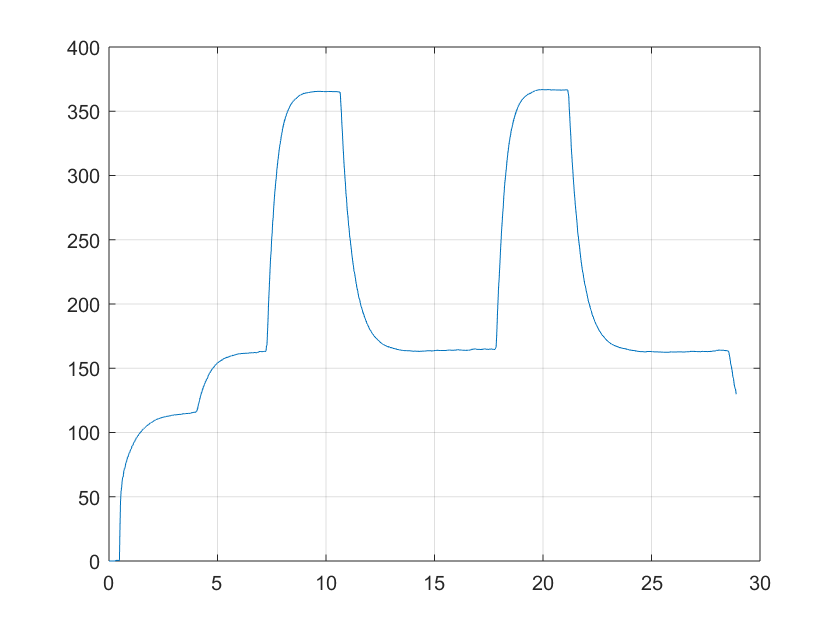

figure(1)
plot(time, rot_speed); grid('on');

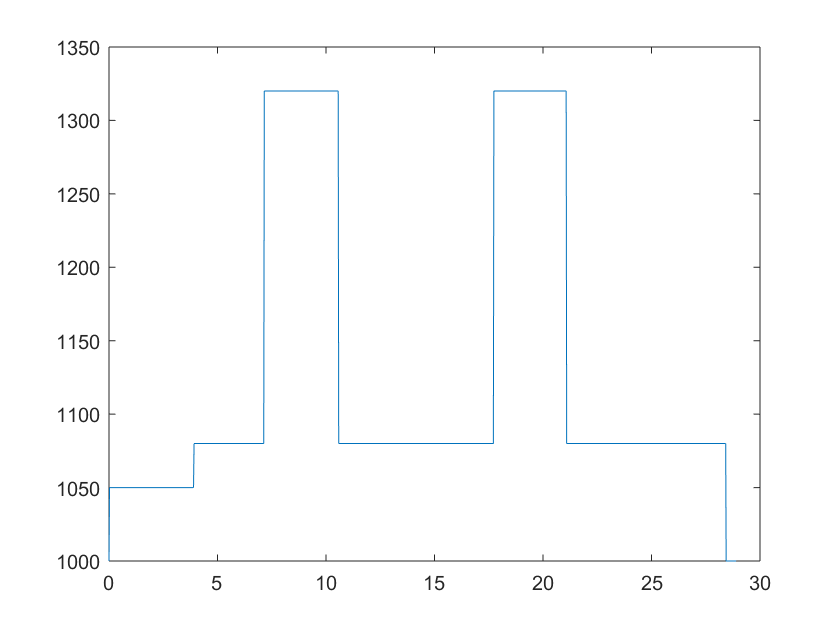



figure(2)
plot(time, ESC_us);

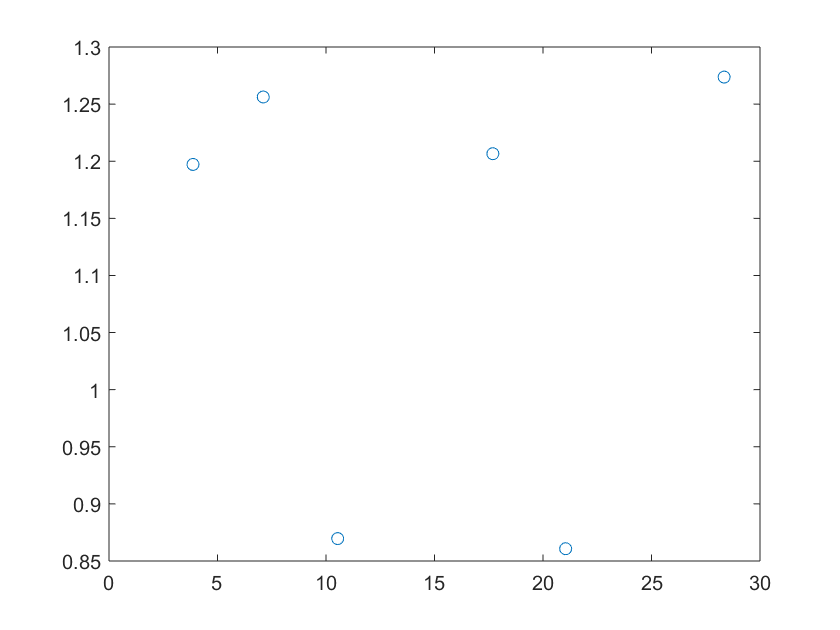


figure(3)
plot(time, Settling_time, 'o-');

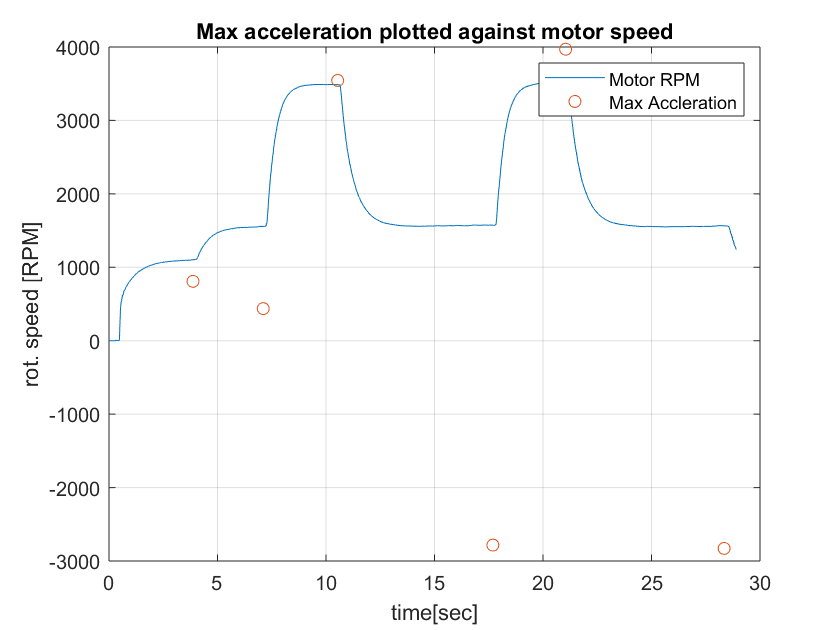


figure(4)
plot(time, rot_speed_rpm, time, Max_Acc, 'o');
title('Max acceleration plotted against motor speed')
xlabel('time[sec]'); ylabel('rot. speed [RPM]'); 
legend('Motor RPM', 'Max Accleration'); grid('on');